# **Lab 6**

**Problem 1**

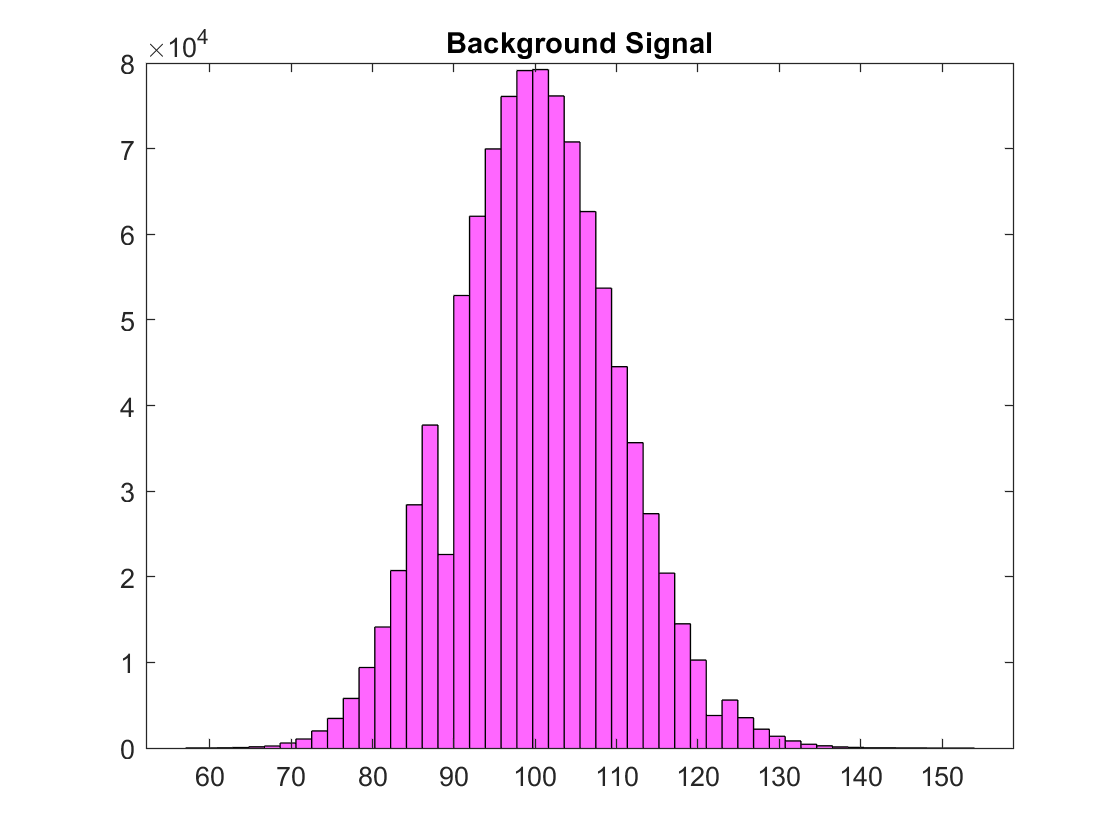

lambda = 100;
x = 1:1000000;
for i= 1:length(x)
    noise(i) = poissrnd(lambda);
end
histogram(noise, 50,"FaceColor",[1 0 1])
title('Background Signal')

sigma = std(noise)

sigma = 10.0127

fiveSigma = 5*sigma;

The 5 sigma sensitivity threshhold is then between values of 50 and 150 (lambda +/- fiveSigma)

**Problem 2**

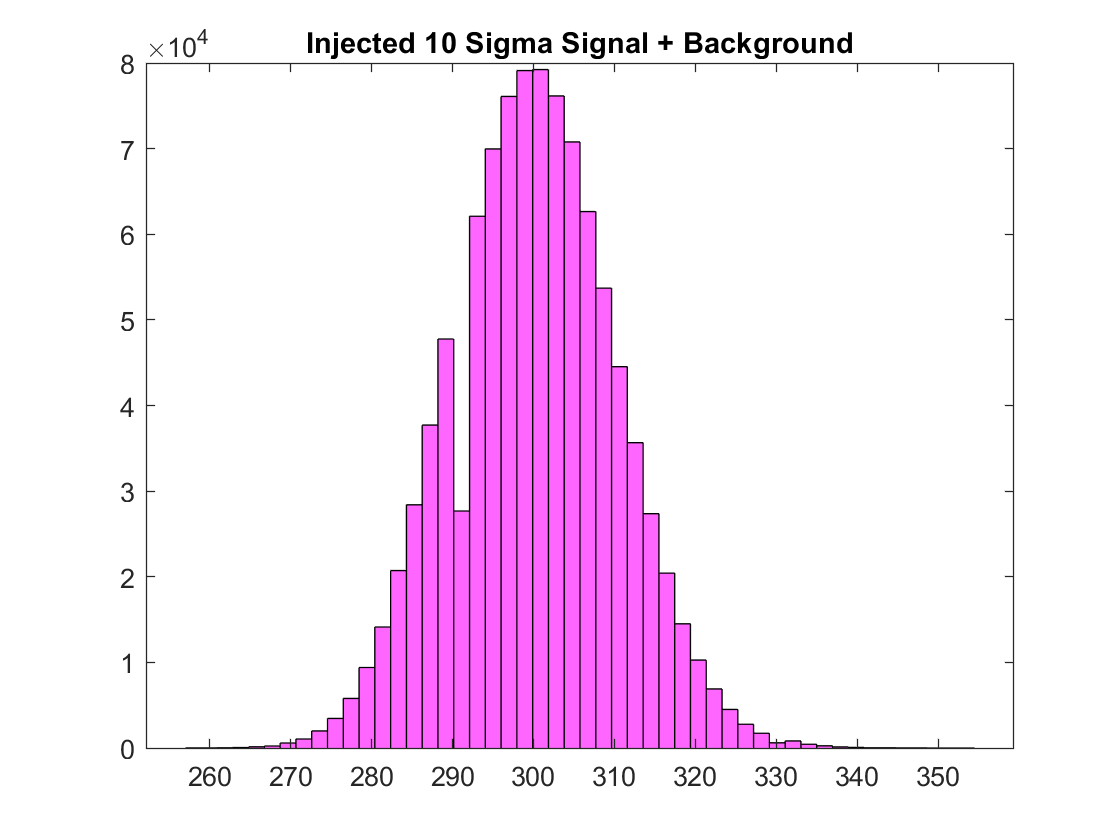

m(1) = 0;
for i=1:1000000
    m(i)=noise(i) + (lambda+10*sigma);
end
histogram(m, 50,"FaceColor", [1 0 1])
title('Injected 10 Sigma Signal + Background')

a) The injected signal is brighter by a median of lambda = 100 (the median is now centered at 300 instead of 200 injected signal). It has a Poisson shape which is expected since Poisson noise was added.

b) Observed value is much more likely to be stronger than true injected signal: the background noise is added to the injected signal and that noise is non-negative with a median of 100. Therefore the distribution of the observed signal is skewed to the right. It is **bigger **than the injected signal and** not symmetric**.

**Problem 3**

a) I chose to inject a distribution of values ranging from 0 to 400. It is 30 sigma to the right and 10 sigma to the left. (We figured the sigma to be around 10 in Problem 1)

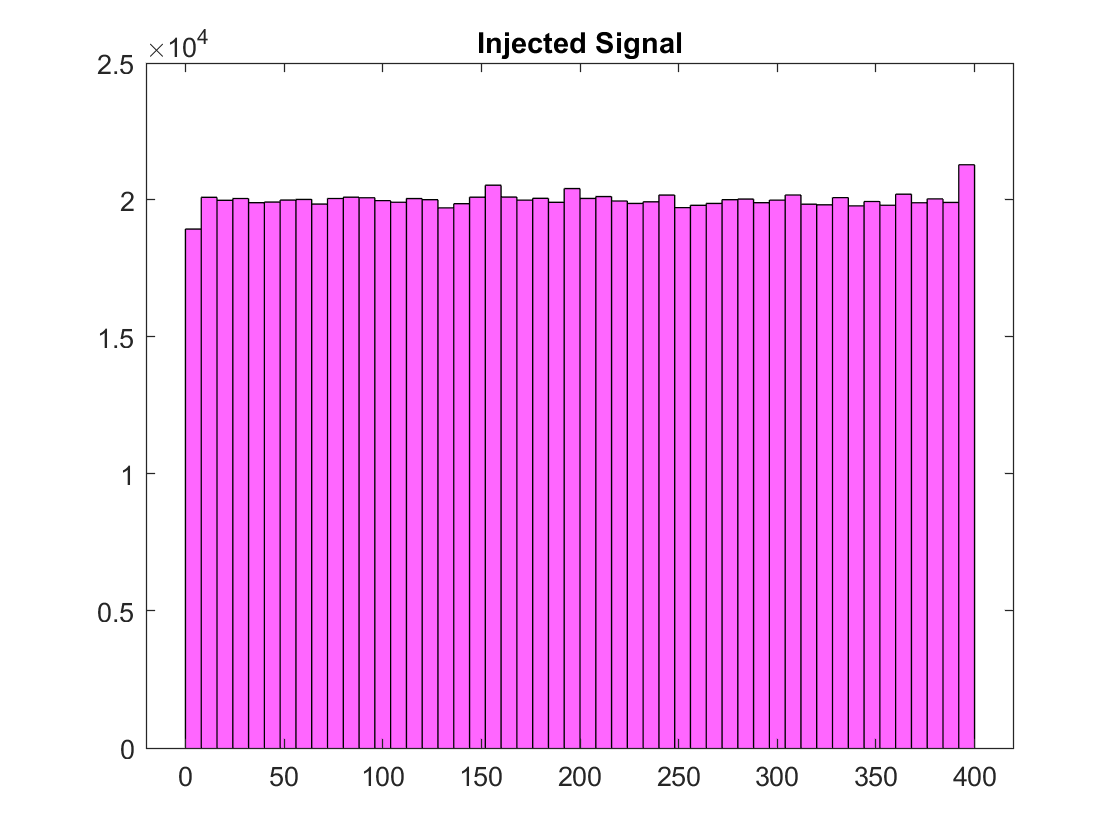

injectedSignal(1)=0;
for i = 1:1000000
    injectedSignal(i) = round(400*rand(1));
end
histogram(injectedSignal, 50, "FaceColor",[1 0 1])
title ('Injected Signal')

Observed signal is a combination of the noise and the injected signal. Plotting the observed signal we can see that there is almost no values of 0 because the noise added has an average of 100 that is added to the injected signal, and there are also signals that extend to 500 and beyound since the max injected signal is 400, and a possible backround noise addition can be in the range 50-150 on average.

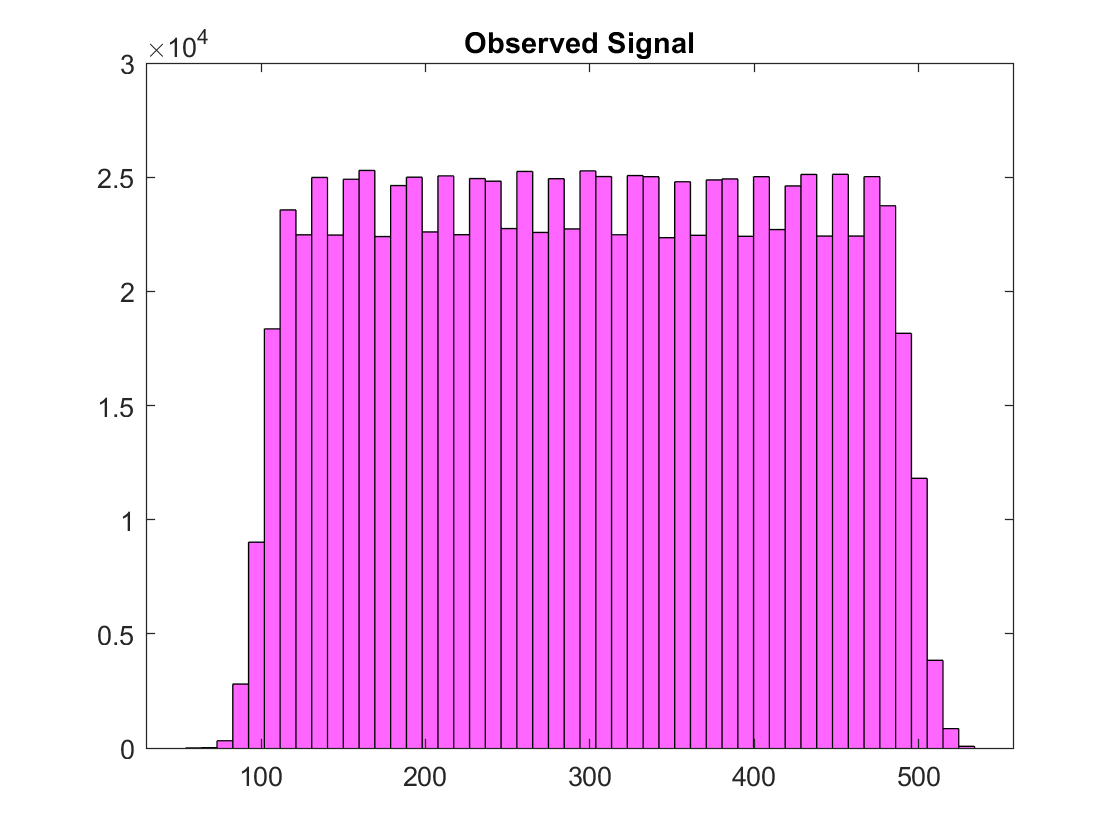

observedSignal = noise+injectedSignal;
histogram(observedSignal,50,"FaceColor",[1 0 1])
title 'Observed Signal'

Now, plotting observed signal vs injected signal, we can see that while the observed signal is directly proportional to the injected signal, it has a Poisson noise. The formula seems to follow

obs = inj + poisson noise

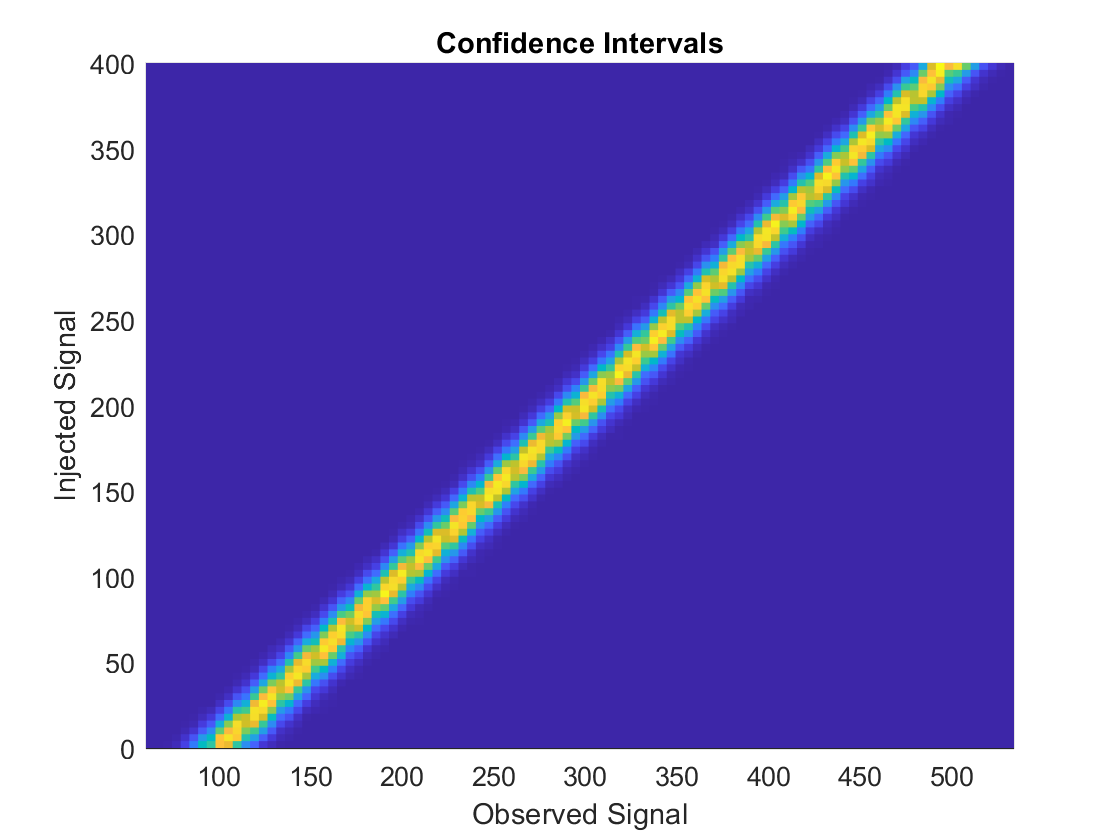

histogram2(observedSignal, injectedSignal,100,'DisplayStyle','tile','ShowEmptyBins','on')
xlabel 'Observed Signal'
ylabel 'Injected Signal'
title 'Confidence Intervals'

b) For a single power injected signal, the observed signal is going to be similar to the one in problem 2. I am going to find all indexes of injected value = 200 and see the range of the observed signal. This is equivalent to slicing the 2d histogram above horisontally at y = 200.

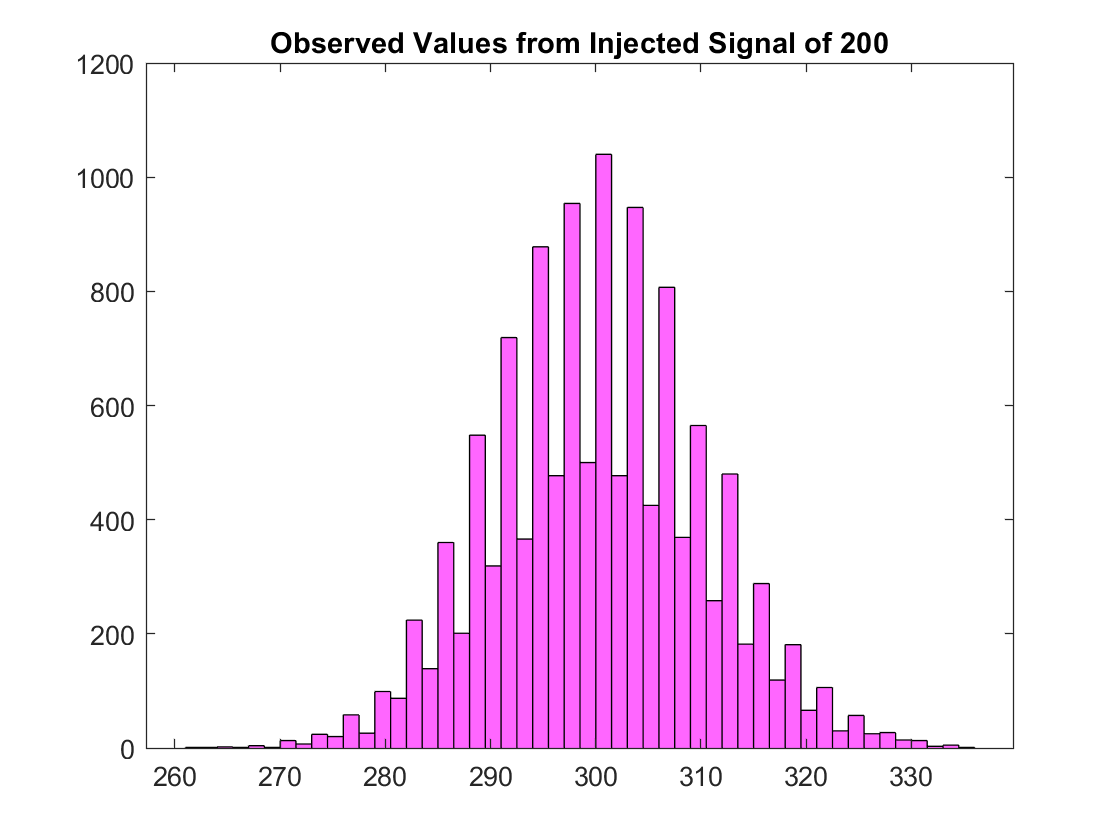

y(1)=0;
for i = 1:1000000
    if injectedSignal(i) == 200
        y = [y ,observedSignal(i)];
    end
end
y = y(2:length(y));%not cound the first one since it was arbitrarily assigned
histogram(y, 50, "FaceColor", [1 0 1])
title('Observed Values from Injected Signal of 200')

It looks similar to where we injected purely 10 sigma signals: it is centered around 300 and looks Poisson distributed.

c) I chose a value of observed signal to be noise+(lambda+15 std) = 350. The process is the same as in b) except for we exchange observed and injected signal. This is equivalent to slicing the 2d histogram above vertically at x = 350.

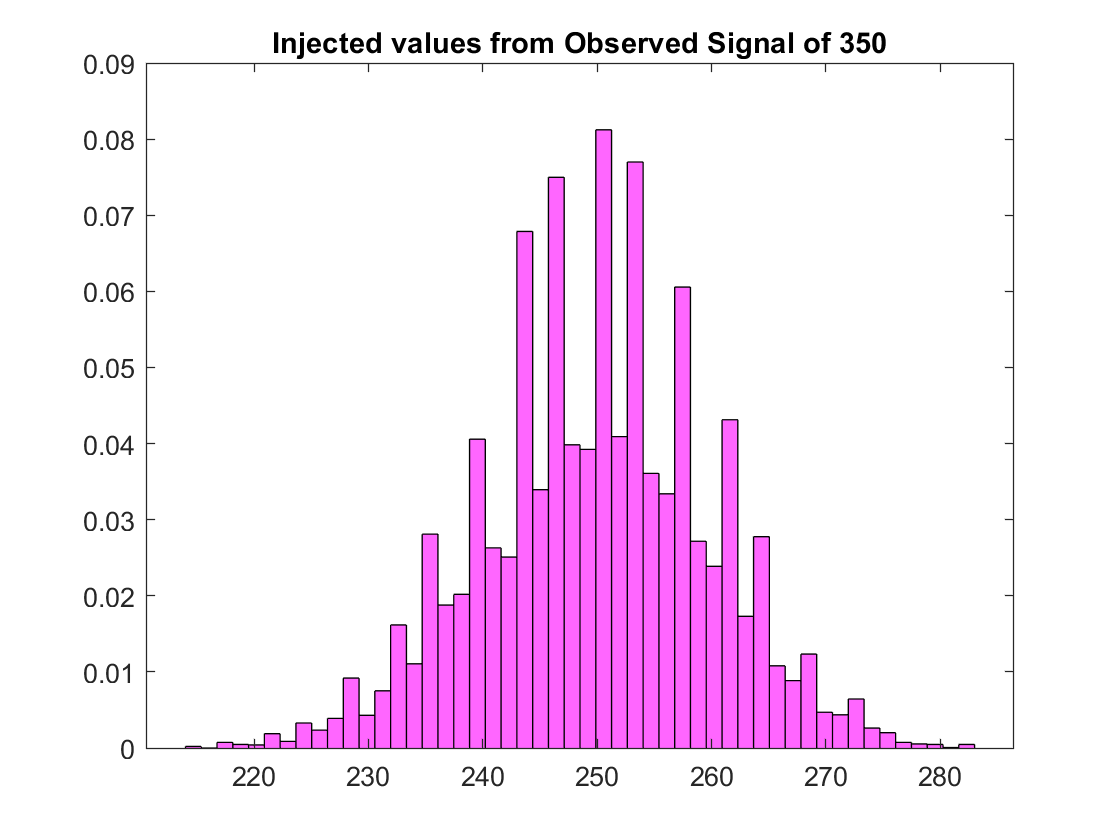

z(1)=0;
for i = 1:1000000
    if observedSignal(i) == 350
        z = [z ,injectedSignal(i)];
    end
end
z = z(2:length(z));%not cound the first one since it was arbitrarily assigned
histogram(z, 50, 'Normalization', 'Probability', "FaceColor", [1 0 1])
title('Injected values from Observed Signal of 350')

This has a mean of 250 and it makes sense since to produce a value of 350, a noise with a 100 median was added.

d) 1 sigma uncertainty means that the values within one standard deviation are accepted as certain to be made by signals. 

average = mean(z)

average = 249.8930

sigma = std(z)

sigma = 9.9013

Therefore the accepted possibility for the injected signal is between 240 and 260. 

e) It is not symmetric, however, because there are more values between 250 and 260 than between 240 and 250. It does not necessarily make sense because standard deviation is reserved for normal distributions and this one is Poisson. 

**Problem 4**

a) 

k(1)=0;
for i = 1:1000000
    if observedSignal(i) == 190
        k = [k ,injectedSignal(i)];
    end
end
k = k(2:length(k));%not cound the first one since it was arbitrarily assigned
h = histogram(k, 50, 'Normalization','Probability',"FaceColor", [1 0 1])

h =   Histogram with properties:

             Data: [1×15425 double]
           Values: [1×50 double]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 2.5200
        BinLimits: [0 126]
    Normalization: 'probability'
        FaceColor: [1 0 1]
        EdgeColor: [0 0 0]

  Show all properties


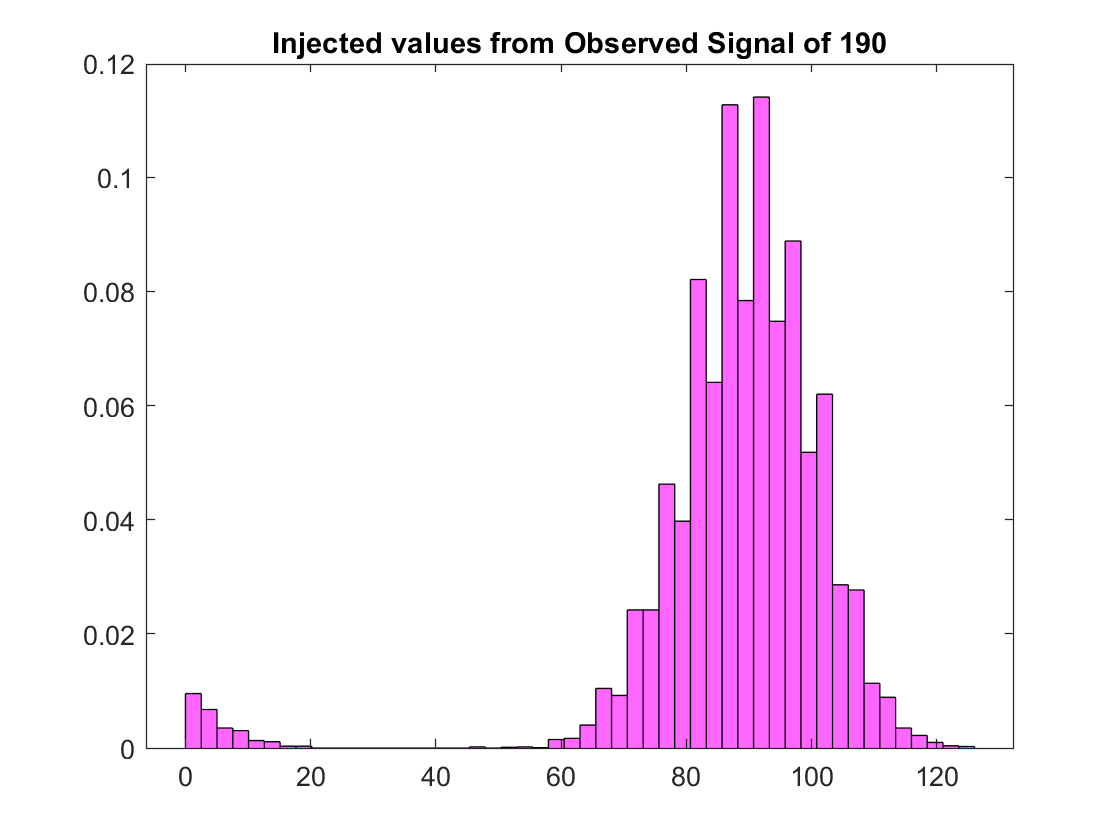

title('Injected values from Observed Signal of 190')

b) If there is a probability that the true signal is 0, that means that there is a chance that the observed signal was produced solely by the background noise since the observed signal is made from background noise and true signal.

c) To calculate 95% confidence upper bound we need to integrate the pdf until 0.95.

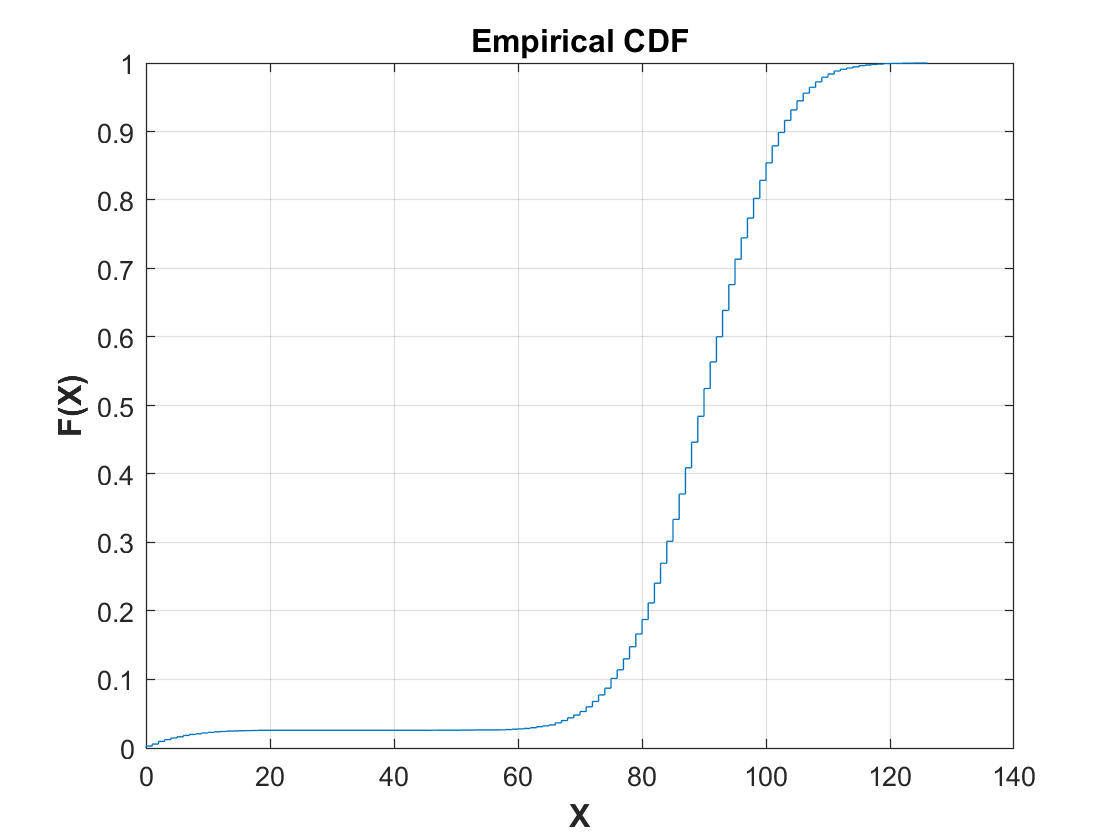

cdfplot(k)

95% value is around value 107.

function cdfplot(X)
% cdfplot(X) 
% displays a plot of the Empirical Cumulative Distribution Function 
% (CDF) of the input array X in the current figure. The empirical 
% CDF y=F(x) is defined as the proportion of X values less than or equal to x.
% If input X is a matrix, then cdfplot(X) parses it to the vector and 
% displays CDF of all values.
%
% EXAMPLE:
% figure;
% cdfplot(randn(1,100));
% hold on;
% cdfplot(-log(1-rand(1,100)));
% cdfplot(sqrt(randn(1,100).^2 + randn(1,100).^2))
% legend('Normal(0,1) CDF', 'Exponential(1) CDF', 'Rayleigh(1) CDF', 4)
% Version 1.0
% Alex Podgaetsky, September 2003
% alex@wavion.co.il
%
% Revisions:
%       Version 1.0 -   initial version
tmp = sort(reshape(X,prod(size(X)),1));
Xplot = reshape([tmp tmp].',2*length(tmp),1);
tmp = [1:length(X)].'/length(X);
Yplot = reshape([tmp tmp].',2*length(tmp),1);
Yplot = [0; Yplot(1:(end-1))];
figure(gcf);
hp = plot(Xplot, Yplot);
ColOrd = get(gca, 'ColorOrder'); 
ord = mod(length(get(gca,'Children')), size(ColOrd,1)); 
set(hp, 'Color', ColOrd((ord==0) + (ord>0)*ord, :));
if ~ishold
     xlabel('X', 'FontWeight','b','FontSize',12);
     ylabel('F(X)', 'FontWeight','b','FontSize',12);
     title('Empirical CDF', 'FontWeight','b','FontSize',12);
     grid on;
end
end